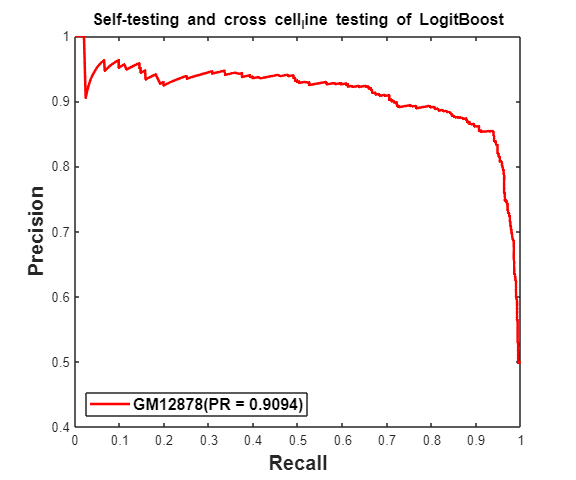

anycell = "K562";   % 只更改细胞名称
openfile = sprintf("trainingWindowIntdisStForR_hs%s.bed", anycell);
fileID = fopen(openfile);
TrainwindowdatadisKc167 = textscan(fileID, '%s %f %f %f %f %f %f %f');
trainingdischiapetKc167 = [TrainwindowdatadisKc167{2:8}];

predictorNames = {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC'};
inputTable = array2table(trainingdischiapetKc167, 'VariableNames', {'EGC', 'GS', 'DIS', 'EWS', 'GWS', 'EEC', 'column_7'});
predictors = inputTable(:, predictorNames);
response = inputTable.column_7;

legendText = {};

template = templateTree('MaxNumSplits', 10);
%classificationEnsemble = fitcensemble(predictors, response, 'Method', 'AdaBoostM1', 'NumLearningCycles', 30, 'Learners', template, 'LearnRate', 0.8, 'ClassNames', [1; 2]);

learners = {template};
classificationEnsemble = fitcensemble(predictors, response, 'Method', 'LogitBoost', 'NumLearningCycles', 16, 'Learners', learners, 'ClassNames', {'1', '2'});


partitionedModel = crossval(classificationEnsemble, 'KFold', 10);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% 计算 K562 的 PR 曲线
[Xpr, Ypr, ~, AUCpr] = perfcurve(trainingdischiapetKc167(:, 7), validationScores(:, 1), 1, 'xCrit', 'reca', 'yCrit', 'prec');
AUCprK562 = round(AUCpr, 4);

% 绘制 K562 的 PR 曲线
%%%%%% plot(Xpr, Ypr, 'LineWidth', 1.9, 'Color', 'red', 'DisplayName', sprintf('K562(PR = %.4f)', AUCprK562));
%%%%%% legendText{1} = sprintf('K562(PR = %.4f)', AUCprK562);
%%%%%% hold on;

% #####hsGM12878#######
filename = sprintf("trainingWindowIntdisStForR_hsGM12878.bed");
fileID = fopen(filename);
Predictwindowdata = textscan(fileID, '%s %f %f %f %f %f %f %f');
Allwindowdata = [Predictwindowdata{2:7}];
trainingdischiapetGM12878 = [Predictwindowdata{2:8}];

[ensemblelabels, ensemblescores] = predict(classificationEnsemble, Allwindowdata);
[Xpr, Ypr, ~, AUCpr] = perfcurve(trainingdischiapetGM12878(:, 7), ensemblescores(:, 1), 1, 'xCrit', 'reca', 'yCrit', 'prec');
AUCprGM12878 = round(AUCpr, 4);

% 绘制 GM12878 的 PR 曲线
plot(Xpr, Ypr, 'LineWidth', 1.9, 'Color', 'red', 'DisplayName', sprintf('GM12878(PR = %.4f)', AUCprGM12878));
legendText{1} = sprintf('GM12878(PR = %.4f)', AUCprGM12878);
hold on;

%######################### 
% #####hsMCF-7#######
%%%%%% filename = sprintf("trainingWindowIntdisStForR_hsMCF-7.bed");
%%%%%% fileID = fopen(filename);
%%%%%% Predictwindowdata = textscan(fileID, '%s %f %f %f %f %f %f %f');
%%%%%% Allwindowdata = [Predictwindowdata{2:7}];
%%%%%% trainingdischiapetMCF7 = [Predictwindowdata{2:8}];

%%%%%% [ensemblelabels, ensemblescores] = predict(classificationEnsemble, Allwindowdata);
%%%%%% [Xpr, Ypr, ~, AUCpr] = perfcurve(trainingdischiapetMCF7(:, 7), ensemblescores(:, 1), 1, 'xCrit', 'reca', 'yCrit', 'prec');
%%%%%% AUCprMCF7 = round(AUCpr, 4);

% 绘制 MCF-7 的 PR 曲线
%%%%%% plot(Xpr, Ypr, 'LineWidth', 1.9, 'Color', [124/255, 187/255, 0/255], 'DisplayName', sprintf('MCF-7(PR = %.4f)', AUCprMCF7));
%%%%%% legendText{3} = sprintf('MCF-7(PR = %.4f)', AUCprMCF7);
%######################### 

% 设置标签和标题
xlabel('Recall', 'FontSize', 15, 'FontWeight', 'bold');
ylabel('Precision', 'FontSize', 15, 'FontWeight', 'bold');
title('Self-testing and cross cell_line testing of LogitBoost', 'FontSize', 12, 'FontWeight', 'bold');


% 设置图例
legend(legendText, 'Location', 'southwest', 'TextColor', 'black', 'FontSize', 12, 'FontWeight', 'bold');

% 设置坐标轴为 1.2:1 的比例
width = 6;  % 设置宽度为6英寸
height = width / 1.2;  % 计算高度
set(gcf, 'Units', 'Inches', 'Position', [1 1 width height]);

hold off;  % 结束保持图形

% 保存图像为 PNG 文件
pngString = sprintf("K562_LogitBoost_self_cross_cellLines_PR_test.png");
print(gcf, pngString, '-dpng', '-r600');  % 设置为600 DPI